# Unbiased Competition Tutorial

This tutorial demonstrates how to implement the unbiased competition model used in [Ardid, Sherfey et al. 2019](https://doi.org/10.1073/pnas.1812535116).

- Goals: Learn how to...

- Structure: After a brief introduction, the first sections in the tutorial show how to load `DynaSim` and set up the different parameters of the model. The execution of the model is done in section Run the simulation.  Visualization and interpretation of the results is explained in section Visualization and interpretation.

- References

## Background

1-2 paragraph. what is cool about this model, example case scenarios.

## Load DynaSim

If you haven't loaded DynaSim, do it.

dynasim_path = '../../..';
addpath(genpath(dynasim_path));

## Model configuration

In this section we specify the initial settings bla bla

### Simulation time definition

What is this, why does it matter?

%% Simulation time definition
tOn = 0;
tOff = 1500;
tspan = [tOn,tOff];
transient = 500;
interval = diff(tspan);
interval

interval = 1500

### Define equations of cell model

What is this, why does it matter?

eqns = 'dV/dt = @current'   

eqns = 'dV/dt = @current'

s = []; % Create DynaSim specification structure

### Model parameters

%% Model parameters

nSPNs = 150; % Number of SPN cells in the pool
multiplicity = [nSPNs,nSPNs];

% Leak current
g_l_D1 = 0.096;
g_l_D2 = 0.1;

% Ca current
g_cat_D1 = 0.018;
g_cat_D2 = 0.025;

### Setting poisson input parameters

%% Setting poisson input parameters

% Background Async mean input
g_extInp = 0.00035;     % in mS/cm^2
baseline_extInp = 30e3; % in spks/s

% Pfc input to SPN (excitatory beta input)
g_pfcInp = g_extInp;

tOn_pfcInp = 500;    % ms
tOff_pfcInp = 1500;  % ms
latency_pfcInp = 40; % ms
dutyPercentage_pfcInp = 50;

% DC Variation
DC_ref = 44e3;          % in spks/s
pfcInp_spont = 0;
pfcInp_DCred = DC_ref/5;
pfcInp_DC = DC_ref;

% AC Variation
AC_ref = 8e3;           % in spks/s
pfcInp_ACred = AC_ref/5;
pfcInp_AC =  AC_ref;

% TODO: esto se tiene que ajustar para los casos AC
freq_pfcInp = 0;
thresholddutycycle_pfcInp = -1;

% TODO: estandarizar nombre variables
pfcInp_DCcond = [pfcInp_spont, pfcInp_DCred, pfcInp_DC]; % AC, reduced_AC];
pfcInp_DCcond_labels = {'Spontaneous', 'DC reduced', 'DC'}; % 'AC', 'reduced AC'};
vary_DC = {
'(D1_SPN,D2_SPN)','DC_pfc_poisson',pfcInp_DCcond
};

thresholdDUTY = cos(pi*dutyPercentage_pfcInp/100);
threshold = [thresholdDUTY, thresholdDUTY];

freq_ref = 25; % High beta
% freq_ref = 20; % Mid beta
% freq_ref = 18; % Low beta
% freq_ref = 10; % Alpha
frequency = [freq_ref, freq_ref];

% pfcInp_ACcond = [pfcInp_ACred, pfcInp_AC];
% pfcInp_ACcond_labels = {'AC reduced', 'AC'};
% vary_AC = {'(D1_SPN,D2_SPN)','AC_pfc_poisson',pfcInp_ACcond;
%     '(D1_SPN,D2_SPN)','thresholddutycycle_pfc_poisson',threshold;
%     '(D1_SPN,D2_SPN)','f_pfc_poisson',frequency}; % it doesn't work

### Setting connection parameters


%% Setting connection parameters

% Connection probabilities
conn_prob_gaba_D1toD1 = 0.26;
conn_prob_gaba_D1toD2 = 0.06;
conn_prob_gaba_D2toD1 = 0.27;
conn_prob_gaba_D2toD2 = 0.36;

% Calculate Gaba conductance for each connection
g_gaba_D1_lowDA = 0.5/multiplicity(1);
g_gaba_D2_lowDA = 1.65*g_gaba_D1_lowDA*multiplicity(1)/multiplicity(2);
f_gaba_D1_highDA = 1.3;
f_gaba_D2_highDA = 0.5;

g_gaba_D1 = g_gaba_D1_lowDA*f_gaba_D1_highDA;
g_gaba_D2 = g_gaba_D2_lowDA*f_gaba_D2_highDA;
cross_inhibition_factor = 1.5;

% Calculate Tau Gaba for each connection
median_tau_gaba = 30.4;      % ms
sig_tau_gaba = 8.2;          % ms
tau_gaba_D1 = median_tau_gaba + sig_tau_gaba*randn(1,multiplicity(1));
tau_gaba_D2 = median_tau_gaba + sig_tau_gaba*randn(1,multiplicity(2));

% Tau STD
tauD_D1_highDA = 1030;    % from 275 % ms
tauD_D2_highDA = 210;     % from 415

### Define populations and connections


%% Main structure

% Population definition
s.populations(1).name = 'D1_SPN';
s.populations(1).size = multiplicity(1);
s.populations(1).equations = eqns;
s.populations(1).mechanism_list = {'spn_iNa','spn_iK','spn_iLeak','spn_iM','spn_iCa','spn_CaBuffer','spn_iKca','spn_iPoisson','spn_ipfcPoisson'};
s.populations(1).parameters = {'cm',1,'g_l',g_l_D1,'g_cat',g_cat_D1,'g_poisson',g_extInp,'baseline_poisson',baseline_extInp,'g_pfc_poisson',g_pfcInp,'onset_pfc_poisson',tOn_pfcInp,'offset_pfc_poisson',tOff_pfcInp,'latency_pfc_poisson',latency_pfcInp}; %,'AC_pfc_poisson',AC_pfcInp, 'f_pfc_poisson',freq_pfcInp,'thresholddutycycle_pfc_poisson',thresholddutycycle_pfcInp};
s.populations(2).name = 'D2_SPN';
s.populations(2).size = multiplicity(2);
s.populations(2).equations = eqns;
s.populations(2).mechanism_list = {'spn_iNa','spn_iK','spn_iLeak','spn_iM','spn_iCa','spn_CaBuffer','spn_iKca','spn_iPoisson','spn_ipfcPoisson'};
s.populations(2).parameters = {'cm',1,'g_l',g_l_D2,'g_cat',g_cat_D2,'g_poisson',g_extInp,'baseline_poisson',baseline_extInp,'g_pfc_poisson',g_pfcInp,'onset_pfc_poisson',tOn_pfcInp,'offset_pfc_poisson',tOff_pfcInp,'latency_pfc_poisson',latency_pfcInp}; %,'AC_pfc_poisson',AC_pfcInp, 'f_pfc_poisson',freq_pfcInp,'thresholddutycycle_pfc_poisson',thresholddutycycle_pfcInp};

% Set connections between populations
s.connections(1).direction = 'D1_SPN->D1_SPN';
s.connections(1).mechanism_list = {'spn_iGABA'};
s.connections(1).parameters = {'conn_prob_gaba',conn_prob_gaba_D1toD1,'g_gaba',g_gaba_D1,'tau_gaba',tau_gaba_D1,'tauD_gaba',tauD_D1_highDA};
s.connections(2).direction = 'D1_SPN->D2_SPN';
s.connections(2).mechanism_list = {'spn_iGABA'};
s.connections(2).parameters = {'conn_prob_gaba',conn_prob_gaba_D1toD2,'g_gaba',cross_inhibition_factor*g_gaba_D1,'tau_gaba', tau_gaba_D1,'tauD_gaba',tauD_D1_highDA};
s.connections(3).direction = 'D2_SPN->D1_SPN';
s.connections(3).mechanism_list = {'spn_iGABA'};
s.connections(3).parameters = {'conn_prob_gaba',conn_prob_gaba_D2toD1,'g_gaba',cross_inhibition_factor*g_gaba_D2,'tau_gaba', tau_gaba_D2,'tauD_gaba',tauD_D2_highDA};
s.connections(4).direction = 'D2_SPN->D2_SPN';
s.connections(4).mechanism_list = {'spn_iGABA'};
s.connections(4).parameters = {'conn_prob_gaba',conn_prob_gaba_D2toD2,'g_gaba',g_gaba_D2,'tau_gaba', tau_gaba_D2,'tauD_gaba',tauD_D2_highDA};

## Run the simulation

%% Simulate the model

% Simulate pfc DC input variation
data = dsSimulate(s,'time_limits',tspan,'vary',vary_DC,'dt',0.05,'solver','rk4');

% Simulate pfc AC input variation
%data = dsSimulate(s,'time_limits',tspan,'vary',vary_AC,'dt',0.05,'solver','rk4');


## Visualization and interpretation

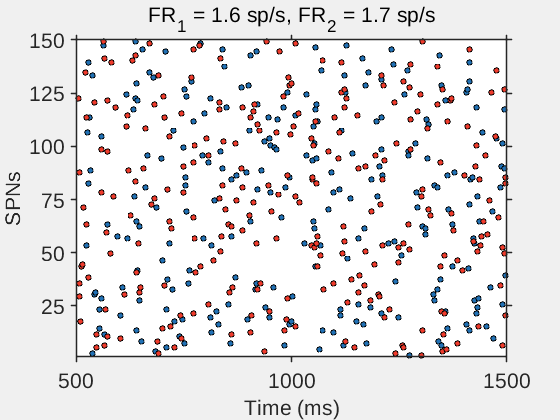

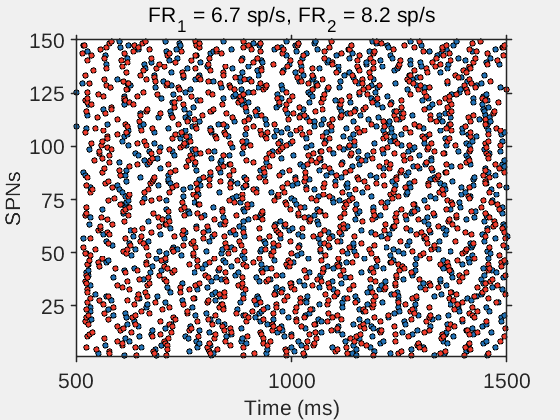

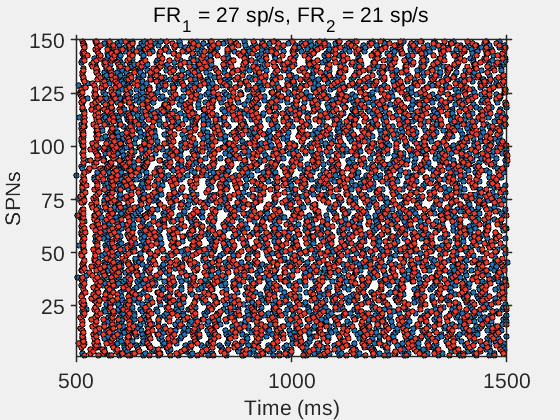

%% Visualization

% Raster plot (Fig. 3A)
for iSim = 1:numel(pfcInp_DCcond) %(pfcInp_ACcond)
    raster{1} = computeRaster(data(:,iSim).time,data(:,iSim).D1_SPN_V);
    raster{2} = computeRaster(data(:,iSim).time,data(:,iSim).D2_SPN_V);
    tl = [tOn+transient, tOff]; % [tOn, tOff];
    rate = plotRaster(multiplicity,tl,raster);
    %title(pfcInp_DCcond_labels{iSim});
end

## TODO: "Personalize" the model